clc
clear all

 Load the saved preprocessed data. Two class corresponds to "REM" vs "Wake" EEG signal

Training = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTrainUS.mat');
Training = Training.Balancedsleep2ClasstrainUSCell;
TrainingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTrainUSLabels.mat');
TrainingLabels = TrainingLabels.TwoClassTrain_US_Labels';
Validation= load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassValidationUS.mat');
Validation = Validation.Balancedsleep2ClassvalidationUSCell;
ValidationLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassValidationUSLabels.mat');
ValidationLabels = ValidationLabels.TwoClassValidation_US_Labels';
Testing = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTestUS.mat');
 Testing = Testing.Balancedsleep2ClasstestUSCell;
TestingLabels = load('C:\courses\ML\project\codes\TrainNetworkProject2\dataset_processed\TwoclassTestUSLabels.mat');
TestingLabels = TestingLabels.TwoClassTest_US_Labels';


 Extract features: Here we consider variety of features used for Non stationary signal analysis such an EEG signal.The features are 1) Autoregressive model coefficients  (of order 4) estimated using Burg method, Shannon entropy for the maximum overlap discrete wavelet  packet transform, The singularity spectrum (Multifractal wavelet leader estimate of the second cumulant of the scaling exponents and the range of holder exponents, Wavelet variance, Hijorth parameters, mean instantaneous frequency and standard features such as mean, variance, kurtosis of the signal) . The time window chosen is 250.

timeWindow = 250;
ARorder = 4;
MODWPTlevel = 4;
[trainFeatures,ValidationFeatures, testFeatures, featureindices] = helperExtractFeatures(Training,Validation,Testing,timeWindow,ARorder,MODWPTlevel);

Computing feature weights by fitting a Neighbourhood component analysis (NCA) model 

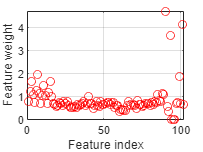

train_reduced = fscnca(trainFeatures,TrainingLabels); 

figure()
plot(train_reduced.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')

 Feature selection using the tolerance level "tol". Currently we kept it as 0.1 in the interest of time. But it can also be set as a hyperparameter.

tol    = 0.1;
selidx = find(train_reduced.FeatureWeights > tol*max(1,max(train_reduced.FeatureWeights)));
trainFeatures1 = trainFeatures(:,selidx);
ValidationFeatures1 = ValidationFeatures(:,selidx);
testFeatures1 = testFeatures(:,selidx);


features = [trainFeatures1; ValidationFeatures1];
labels = [TrainingLabels;ValidationLabels];

 Fit an SVM model and perform hyperparameter tuning on parameters such as Kernel (polynomial, guassian, linear), polynomial order, kernel scale etc.

rng(1)
model = fitcecoc(...
    features,...
    labels,...
    'Learners','svm',...
    'Coding','onevsone',...
    'ClassNames',{'REM','Wake'},'OptimizeHyperparameters','all',...
    'HyperparameterOptimizationOptions',struct('MaxTime',4*60*60,'AcquisitionFunctionName',...
    'expected-improvement-plus'));

|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale | KernelFuncti-| PolynomialOr-|  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | on           | der          |              |
|=================================================================================================================================================================|
|    1 | Best   |     0.15994 |      20.522 |     0.15994 |     0.15994 |     onevsone |    0.0049535 |            - |       linear |            - |         true |
|    2 | Accept |     0.37086 |      1194.6 |     0.15994 |     0.22232 |     onevsall |     0.017242 |            - |   polynomial |            3 |         true |
|    3 | Best   


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 7691.7696 seconds
Total objective function evaluation time: 7656.435

Best observed feasible point:
     Coding     BoxConstraint    KernelScale    KernelFunction    PolynomialOrder    Standardize
    ________    _____________    ___________    ______________    _______________    ___________

    onevsall       404.52           76.7           gaussian             NaN             false   

Observed objective function value = 0.079813
Estimated objective function value = 0.07993
Function evaluation time = 216.5894

Best estimated feasible point (according to models):
     Coding     BoxConst

 Save the extracted features and model. Here "US" stands for Majority undersampling. While considering SMOTE, replace US by SMOTE.

save('C:\courses\ML\project\SVM_2_class\trained_model_SVM_US.mat','model');
save('C:\courses\ML\project\SVM_2_class\Training_features_SVM_US.mat','trainFeatures');
save('C:\courses\ML\project\SVM_2_class\Validation_features_SVM_US.mat','ValidationFeatures');
save('C:\courses\ML\project\SVM_2_class\Testing_features_SVM_US.mat','testFeatures');
save('C:\courses\ML\project\SVM_2_class\Trainingred_features_SVM_US.mat','trainFeatures1');
save('C:\courses\ML\project\SVM_2_class\Validationred_features_SVM_US.mat','ValidationFeatures1');
save('C:\courses\ML\project\SVM_2_class\Testingred_features_SVM_US.mat','testFeatures1');
save('C:\courses\ML\project\SVM_2_class\TestingINDICES_features_SVM_US.mat','selidx');
save('C:\courses\ML\project\SVM_2_class\Training_featureweights_SVM_US.mat','train_reduced');

Support functions

function [trainFeatures,ValidationFeatures, testFeatures,featureindices] = helperExtractFeatures(trainData,ValData,testData,T,AR_order,level)
% This function is only in support of XpwWaveletMLExample. It may change or
% be removed in a future release.
trainFeatures = [];
testFeatures = [];
ValidationFeatures = [];
for idx =1:size(trainData,1)
    x = trainData{idx,:};
    x = detrend(x,0);
    arcoefs = blockAR(x,AR_order,T);
    se = shannonEntropy(x,T,level);
    [cp,rh] = leaders(x,T);
    wvar = modwtvar(modwt(x,'db2'),'db2');
    [mobility,complexity] = HjorthParameters(x);
    ifq = instfreq(x,200);
    trainFeatures = [trainFeatures; arcoefs se cp rh wvar' mobility complexity mean(ifq) mean(x) var(x) kurtosis(x)]; %#ok<AGROW>
    
end

for idx =1:size(ValData,1)
    x1 = ValData{idx,:};
    x1 = detrend(x1,0);
    arcoefs = blockAR(x1,AR_order,T);
    se = shannonEntropy(x1,T,level);
    [cp,rh] = leaders(x1,T);
    wvar = modwtvar(modwt(x1,'db2'),'db2');
        [mobility,complexity] = HjorthParameters(x);
    ifq = instfreq(x,200);
    ValidationFeatures = [ValidationFeatures;arcoefs se cp rh wvar' mobility complexity mean(ifq) mean(x) var(x) kurtosis(x)]; %#ok<AGROW>
    
end


for idx =1:size(testData,1)
    x1 = testData{idx,:};
    x1 = detrend(x1,0);
    arcoefs = blockAR(x1,AR_order,T);
    se = shannonEntropy(x1,T,level);
    [cp,rh] = leaders(x1,T);
    wvar = modwtvar(modwt(x1,'db2'),'db2');
        [mobility,complexity] = HjorthParameters(x);
    ifq = instfreq(x,200);
    testFeatures = [testFeatures;arcoefs se cp rh wvar' mobility complexity mean(ifq) mean(x) var(x) kurtosis(x)]; %#ok<AGROW>
    
end
 
featureindices = struct();
% 4*8
featureindices.ARfeatures = 1:32;
startidx = 33;
endidx = 33+(16*8)-1;
featureindices.SEfeatures = startidx:endidx;
startidx = endidx+1;
endidx = startidx+7;
featureindices.CP2features = startidx:endidx;
startidx = endidx+1;
endidx = startidx+7;
featureindices.HRfeatures = startidx:endidx;
startidx = endidx+1;
endidx = startidx+13;
featureindices.WVARfeatures = startidx:endidx;
end


function se = shannonEntropy(x,numbuffer,level)
numwindows = numel(x)/numbuffer;
y = buffer(x,numbuffer);
se = zeros(2^level,size(y,2));
for kk = 1:size(y,2)
    wpt = modwpt(y(:,kk),level);
    % Sum across time
    E = sum(wpt.^2,2);
    Pij = wpt.^2./E;
    % The following is eps(1)
    se(:,kk) = -sum(Pij.*log(Pij+eps),2);
end
se = reshape(se,2^level*numwindows,1);
se = se';
end


function arcfs = blockAR(x,order,numbuffer)
numwindows = numel(x)/numbuffer;
y = buffer(x,numbuffer);
arcfs = zeros(order,size(y,2));
for kk = 1:size(y,2)
    artmp =  arburg(y(:,kk),order);
    arcfs(:,kk) = artmp(2:end);
end
arcfs = reshape(arcfs,order*numwindows,1);
arcfs = arcfs';
end


function [cp,rh] = leaders(x,numbuffer)
y = buffer(x,numbuffer);
cp = zeros(1,size(y,2));
rh = zeros(1,size(y,2));
for kk = 1:size(y,2)
    [~,h,cptmp] = dwtleader(y(:,kk));
    cp(kk) = cptmp(2);
    rh(kk) = range(h);
end
end

function [mobility,complexity] = HjorthParameters(xV)

n = length(xV);
dxV = diff([0;xV]);
ddxV = diff([0;dxV]);
mx2 = mean(xV.^2);
mdx2 = mean(dxV.^2);
mddx2 = mean(ddxV.^2);

mob = mdx2 / mx2;
complexity = sqrt(mddx2 / mdx2 - mob);
mobility = sqrt(mob);
end


